Select source data folder. Data folder shold have the following structure:

src_data

----damaged

----healthy

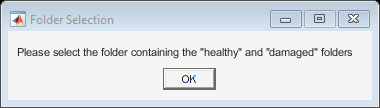

[fileStruct, folderPathStruct] = selectFolderAndListFiles();

fileStruct: struct with the filenames of each folder ("healthy" and "damaged").

folderPath: absolute path of where folders "healthy" and "damaged" are located.

%%%%%%%%%%%

If "`Error using processTDMSFiles Specified TDMS file might be unsupported v1.0`"

Use the the live script **tscm.data_conversion.mlx**

%%%%%%%%%%%

fileList_healthy = fileStruct.healthy;
fileList_damaged_GF = fileStruct.damaged.GF_Ritzel;
fileList_damaged_SIZA = fileStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad;

The struct has been divided in two lists, which are going to be converted into a struct of tables containing all files

decimateFactor = 10;

tdmsTables_healthy = processTDMSFiles(fileList_healthy, folderPath, decimateFactor);
tdmsTables_damaged_GF = processTDMSFiles(fileList_damaged_GF, folderPathStruct.damaged.GF_Ritzel, decimateFactor);
tdmsTables_damaged_SIZA = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);

tableFeatures_healthy = extractTableFeatures(tdmsTables_healthy);
tableFeatures_damaged_GF = extractTableFeatures(tdmsTables_damaged_GF);
tableFeatures_damaged_SIZA = extractTableFeatures(tdmsTables_damaged_SIZA);

exportTableToCSV(tableFeatures_healthy);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_healthy_fs_10kHz.csv


exportTableToCSV(tableFeatures_damaged_GF);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_damaged_fs_10kHz.csv


exportTableToCSV(tableFeatures_damaged_SIZA);